SETUP: Load all of the files into the workspace and parse out the data simultaenously

clear all
close all
clc
format longG

const = getConst();
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% directory load for pitot tube
pitotfiles = dir(['2002Data/PitotStatic/']);

for i = 3:numel(pitotfiles)                                 %This for loop is called for every pitot data file
    Pitot = table2array(readtable(['2002Data/PitotStatic/',pitotfiles(i).name]));
    y = Pitot(:,13);
    y_ind = find(diff(y)>1);
    y_ind = [0;y_ind;length(y)];
    
    Data = NaN(length(y_ind)-1, 13);   
    for j = 1:(length(y_ind)-1)                             %This for loop will be called for parsing out the data in each file
        %This for loop is going to be called 5 times for each section of data
        temp = mean(Pitot(y_ind(j)+1:y_ind(j+1),1:13));        %Find the mean of all of those rows
        %tempstdev = std(Pitot(y_ind(j)+1:y_ind(j+1),:));
        %tempSEM = tempstdev / sqrt(diff(y_ind(1:2,1)));     %Find the SEM of all of those rows
        Data(j,:) = [temp];                                 %Store each 
        %Datastdev(j,:) = [tempstdev];
        %DataSEM(j,:) = [tempSEM];
    end
      
    %Create the struct of all our data here
     PitotTrialHolder(i-2).v = Data;                          %Take Data from the for loop (which basically compressed the data from 1 file into a 5x7 matrix
     %PitotTrialHolderSEM(i).v = DataSEM;                    %Take DataSEM from the for loop (which basically compressed the error from averaging into a 5x7 matrix for each measurement)
    
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 %% directory load for venturi tube
venturifiles = dir(['2002Data/VenturiTube/']);

%To understand this, see comments for Pitot Trial data, it's essentially the same code
for i = 3:numel(venturifiles)
    Venturi = table2array(readtable(['2002Data/VenturiTube/',venturifiles(i).name]));
    y = Venturi(:,13);
    y_ind = find(diff(y)>1);
    y_ind = [0;y_ind;length(y)];
    
    Data = NaN(length(y_ind)-1, 13);
    for j = 1:(length(y_ind)-1)
        temp = mean(Venturi(y_ind(j)+1:y_ind(j+1),1:13));
        %tempstdev = std(Venturi(y_ind(j)+1:y_ind(j+1),:));
        %tempSEM = tempstdev / sqrt(diff(y_ind(1:2,1)));
        Data(j,:) = [temp];
        %Datastdev(j,:) = [tempstdev];
        %DataSEM(j,:) = [tempSEM];
    end
    
    %Create the struct of all our data here
    VenturiTrialHolder(i-2).v = Data;
    %VenturiTrialHolderSEM(i).v = DataSEM;
end

As a result of the above code, the trial holders (VenturiTrialHolder for example) are arrays. Each index of the trial holder will represent a struct that holds a singular element, v. The element, v, is an array that has rows of each voltage tested during the trial and other columns of useful data that resulted from that tested voltage.

If this is confusing to you, then imagine a big folder on your computer called VenturiTrialHolder that holds 12 others folders that hold a singular file that is a 5x7 array where the rows represent a test for a certain voltage and the columns represent dependent variables when you change the voltage.

Each of the TrialHolder arrays have 3 sets of data per voltage located at (index + (iterator)*4)

ORGANIZING DATA: This part will try to compress the 3 sets of data per voltage in the TrialHolder arrays to get 1 row per voltage.

for i = 1:4
    fivebythirteen = NaN(5,13);
    for j = 1:5
        temporary = ([VenturiTrialHolder(i).v(j,:);VenturiTrialHolder(i+4).v(j,:);VenturiTrialHolder(i+8).v(j,:)]);
        %temporarySEM = ([VenturiTrialHolderSEM(i).v(j,:);VenturiTrialHolderSEM(i+4).v(j,:);VenturiTrialHolderSEM(i+8).v(j,:)]);
        %for k = 1:6
            temporaryRow = [mean(temporary(:,:))];
            %temporaryRowSEM(k) = [weightedAVGG(temporary(:,k),temporarySEM(:,k))];
            
        %end
        %temporaryRow(7) = mean(temporary(:,7));
        %temporaryRowSEM(7) = mean(temporarySEM(:,7));
        fivebythirteen(j,:) = temporaryRow;
        %fivebysevenSEM(j,:) = temporaryRowSEM;
        
    end
    CompressedVenturiTrialHolder(i).v = fivebythirteen;
    %CompressedVenturiTrialHolderSEM(i).v = fivebysevenSEM;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1:4
    fivebythirteen = NaN(5,13);
    for j = 1:5
        if (i == 1)
            temporary = ([PitotTrialHolder(i).v(j,:);PitotTrialHolder(i+4).v(j,:);PitotTrialHolder(i+8).v(j,:); PitotTrialHolder(i+12).v(j,:)]);
        else
   
            temporary = ([PitotTrialHolder(i).v(j,:);PitotTrialHolder(i+4).v(j,:);PitotTrialHolder(i+8).v(j,:)]);
        end
        %temporarySEM = ([PitotTrialHolderSEM(i).v(j,:);PitotTrialHolderSEM(i+4).v(j,:);PitotTrialHolderSEM(i+8).v(j,:)]);
        %for k = 1:6
        
            temporaryRow = [mean(temporary(:,:))];
            %temporaryRowSEM(k) = [weightedAVGG(temporary(:,k),temporarySEM(:,k))];
        %end
        %temporaryRow(7) = mean(temporary(:,7));
        %temporaryRowSEM(7) = mean(temporarySEM(:,7));
        fivebythirteen(j,:) = temporaryRow;
        %fivebysevenSEM(j,:) = temporaryRowSEM;
    end
    CompressedPitotTrialHolder(i).v = fivebythirteen;
    %CompressedVenturiTrialHolderSEM(i).v = fivebysevenSEM;
end

This section of the code will organize the compressed trial holders 4,1,3,2

It is hard coded because using for loops to do this indexing is really hard and I don't feel like thinking.

OrgAndCompPitotTrialHolder = NaN(20,13);
OrgAndCompPitotTrialHolder(1 ,:) = CompressedPitotTrialHolder(4).v(1,:);
OrgAndCompPitotTrialHolder(2 ,:) = CompressedPitotTrialHolder(1).v(1,:);
OrgAndCompPitotTrialHolder(3 ,:) = CompressedPitotTrialHolder(3).v(1,:);
OrgAndCompPitotTrialHolder(4 ,:) = CompressedPitotTrialHolder(2).v(1,:);
OrgAndCompPitotTrialHolder(5 ,:) = CompressedPitotTrialHolder(4).v(2,:);
OrgAndCompPitotTrialHolder(6 ,:) = CompressedPitotTrialHolder(1).v(2,:);
OrgAndCompPitotTrialHolder(7 ,:) = CompressedPitotTrialHolder(3).v(2,:);
OrgAndCompPitotTrialHolder(8 ,:) = CompressedPitotTrialHolder(2).v(2,:);
OrgAndCompPitotTrialHolder(9 ,:) = CompressedPitotTrialHolder(4).v(3,:);
OrgAndCompPitotTrialHolder(10,:) = CompressedPitotTrialHolder(1).v(3,:);
OrgAndCompPitotTrialHolder(11,:) = CompressedPitotTrialHolder(3).v(3,:);
OrgAndCompPitotTrialHolder(12,:) = CompressedPitotTrialHolder(2).v(3,:);
OrgAndCompPitotTrialHolder(13,:) = CompressedPitotTrialHolder(4).v(4,:);
OrgAndCompPitotTrialHolder(14,:) = CompressedPitotTrialHolder(1).v(4,:);
OrgAndCompPitotTrialHolder(15,:) = CompressedPitotTrialHolder(3).v(4,:);
OrgAndCompPitotTrialHolder(16,:) = CompressedPitotTrialHolder(2).v(4,:);
OrgAndCompPitotTrialHolder(17,:) = CompressedPitotTrialHolder(4).v(5,:);
OrgAndCompPitotTrialHolder(18,:) = CompressedPitotTrialHolder(1).v(5,:);
OrgAndCompPitotTrialHolder(19,:) = CompressedPitotTrialHolder(3).v(5,:);
OrgAndCompPitotTrialHolder(20,:) = CompressedPitotTrialHolder(2).v(5,:);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
OrgAndCompVenturiTrialHolder = NaN(20,13);
OrgAndCompVenturiTrialHolder(1 ,:) = CompressedVenturiTrialHolder(4).v(1,:);
OrgAndCompVenturiTrialHolder(2 ,:) = CompressedVenturiTrialHolder(1).v(1,:);
OrgAndCompVenturiTrialHolder(3 ,:) = CompressedVenturiTrialHolder(3).v(1,:);
OrgAndCompVenturiTrialHolder(4 ,:) = CompressedVenturiTrialHolder(2).v(1,:);
OrgAndCompVenturiTrialHolder(5 ,:) = CompressedVenturiTrialHolder(4).v(2,:);
OrgAndCompVenturiTrialHolder(6 ,:) = CompressedVenturiTrialHolder(1).v(2,:);
OrgAndCompVenturiTrialHolder(7 ,:) = CompressedVenturiTrialHolder(3).v(2,:);
OrgAndCompVenturiTrialHolder(8 ,:) = CompressedVenturiTrialHolder(2).v(2,:);
OrgAndCompVenturiTrialHolder(9 ,:) = CompressedVenturiTrialHolder(4).v(3,:);
OrgAndCompVenturiTrialHolder(10,:) = CompressedVenturiTrialHolder(1).v(3,:);
OrgAndCompVenturiTrialHolder(11,:) = CompressedVenturiTrialHolder(3).v(3,:);
OrgAndCompVenturiTrialHolder(12,:) = CompressedVenturiTrialHolder(2).v(3,:);
OrgAndCompVenturiTrialHolder(13,:) = CompressedVenturiTrialHolder(4).v(4,:);
OrgAndCompVenturiTrialHolder(14,:) = CompressedVenturiTrialHolder(1).v(4,:);
OrgAndCompVenturiTrialHolder(15,:) = CompressedVenturiTrialHolder(3).v(4,:);
OrgAndCompVenturiTrialHolder(16,:) = CompressedVenturiTrialHolder(2).v(4,:);
OrgAndCompVenturiTrialHolder(17,:) = CompressedVenturiTrialHolder(4).v(5,:);
OrgAndCompVenturiTrialHolder(18,:) = CompressedVenturiTrialHolder(1).v(5,:);
OrgAndCompVenturiTrialHolder(19,:) = CompressedVenturiTrialHolder(3).v(5,:);
OrgAndCompVenturiTrialHolder(20,:) = CompressedVenturiTrialHolder(2).v(5,:);

This next section will calculate Velocities using inputs from the trial holder data and propogate error

The output of this section will be put into VelocityDataPitot and VelocityDataVenturi which will be 20 rows by 3 columns

The 3 columns will be Velocity, Error, and Voltage respectively

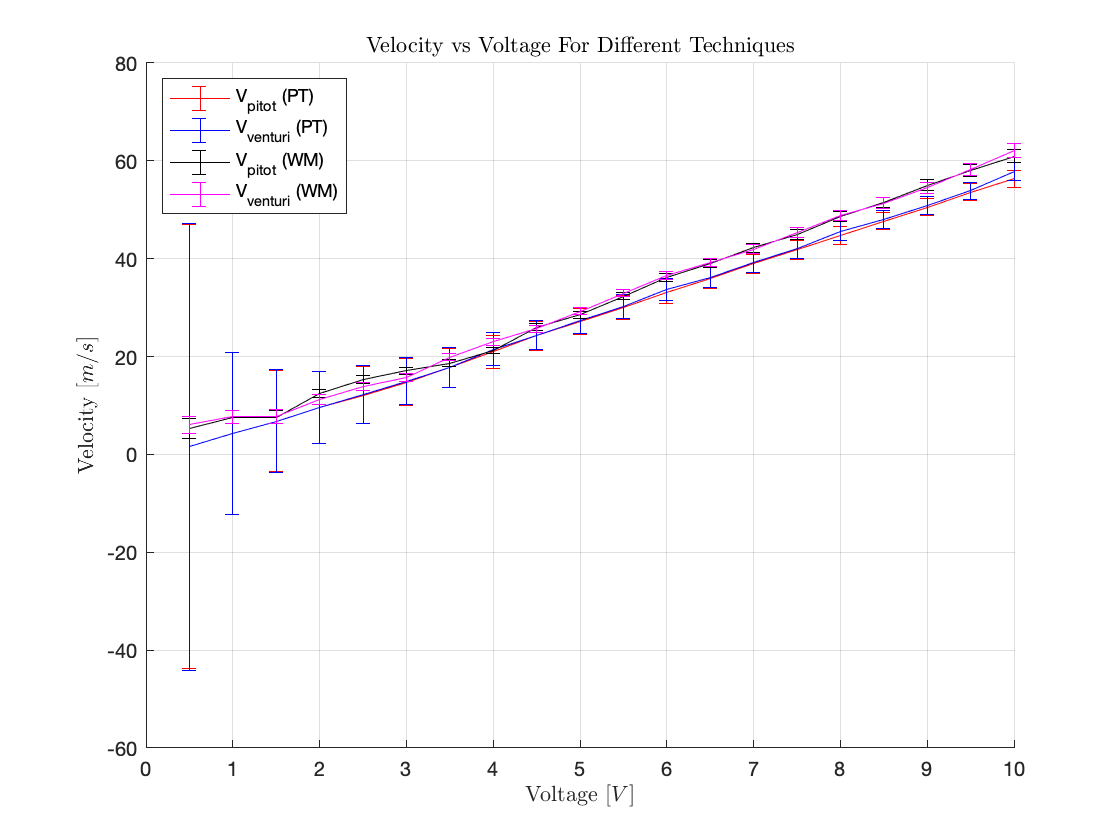

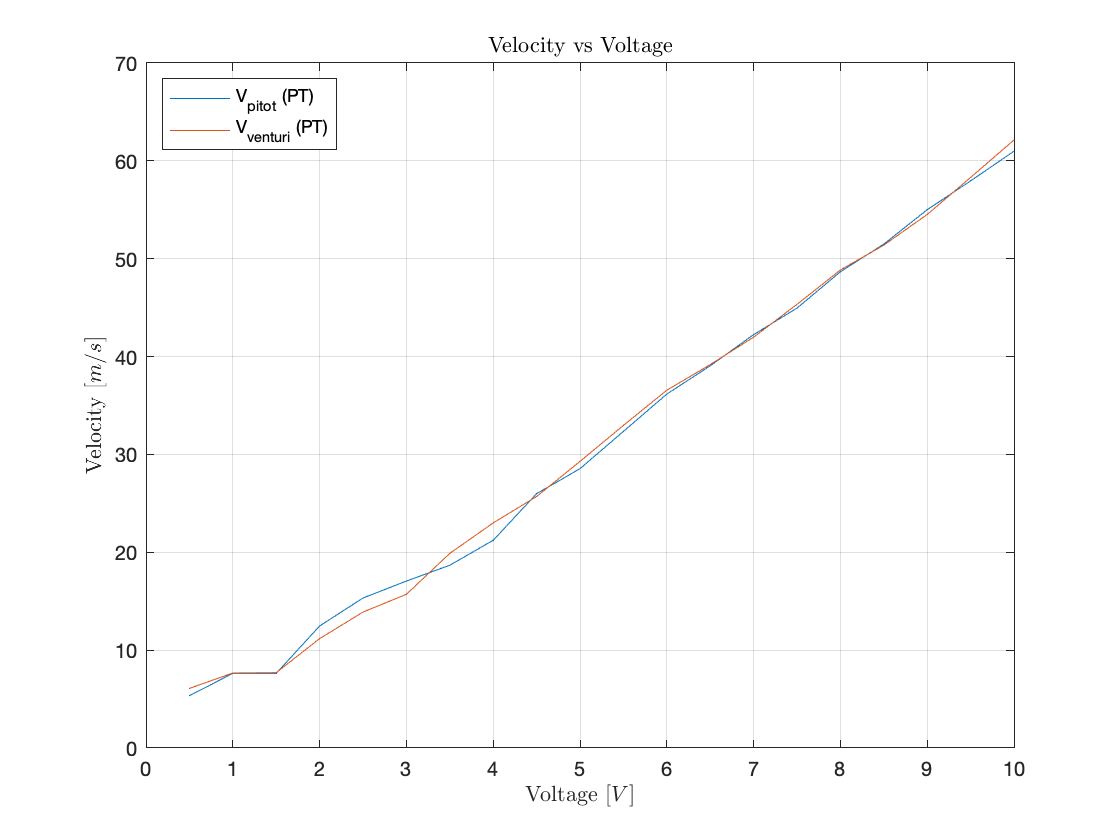

VelocityDataPitot = NaN(20,3);
for i = 1:20
    temporaryRow = NaN(1,3);
    temp = (OrgAndCompPitotTrialHolder(i,6) + OrgAndCompPitotTrialHolder(i,5))/2;
    temporaryRow(1,1) = PitotEquation(temp,OrgAndCompPitotTrialHolder(i,2),OrgAndCompPitotTrialHolder(i,1));
    temporaryRow(1,2) = PitotErrorProp(temp,OrgAndCompPitotTrialHolder(i,2),OrgAndCompPitotTrialHolder(i,1),const.dynPError,const.ambPError,const.tempProbeError);
    temporaryRow(1,3) = OrgAndCompPitotTrialHolder(i,13);
    VelocityDataPitot(i,:) = temporaryRow;
end
%% Velocity voltage plot
    figure
    hold on
    errorbar(VelocityDataPitot(:, 3),VelocityDataPitot(:, 1), VelocityDataPitot(:,2), 'Color', 'r')
    xlabel('Voltage [$V$]')
    ylabel('Velocity [$m/s$]')
    legend({'Pitot with Error'}, 'Location', 'northwest')
    title('Velocity vs Voltage (From Pitot)')
    grid on
    set(0,'defaultTextInterpreter','latex')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
VelocityDataVenturi = NaN(20,3);
for i = 1:20
    temporaryRow = NaN(1,3);
    temp = (OrgAndCompVenturiTrialHolder(i,6) + OrgAndCompVenturiTrialHolder(i,5))/2;
    temporaryRow(1,1) = VenturiEquation(temp,OrgAndCompVenturiTrialHolder(i,2),OrgAndCompVenturiTrialHolder(i,1));
    temporaryRow(1,2) = VenturiErrorProp(temp,OrgAndCompVenturiTrialHolder(i,2),OrgAndCompVenturiTrialHolder(i,1),const.dynPError,const.ambPError,const.tempProbeError);
    temporaryRow(1,3) = OrgAndCompVenturiTrialHolder(i,13);
    VelocityDataVenturi(i,:) = temporaryRow;
end
%% Velocity voltage plot
    %figure
    %plot(VelocityDataVenturi(:, 3),VelocityDataVenturi(:, 1))
    hold on
    errorbar(VelocityDataVenturi(:, 3),VelocityDataVenturi(:, 1), VelocityDataVenturi(:,2), 'Color', 'b')
    xlabel('Voltage [$V$]')
    ylabel('Velocity [$m/s$]')
    legend({'Venturi with Error'}, 'Location', 'northwest')
    title('Velocity vs Voltage (From Venturi)')
    %grid on
    %hold off
    
    set(0,'defaultTextInterpreter','latex')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%WATER MANOMETER STUFF
    PitotT = [OrgAndCompPitotTrialHolder(:,13),OrgAndCompPitotTrialHolder(:,1)];
    VenturiT = [OrgAndCompVenturiTrialHolder(:,13),OrgAndCompVenturiTrialHolder(:,1)];
    PitotP = [OrgAndCompPitotTrialHolder(:,13),OrgAndCompPitotTrialHolder(:,2)];
    VenturiP = [OrgAndCompVenturiTrialHolder(:,13), OrgAndCompVenturiTrialHolder(:,2)];
    [v_pitot v_venturi] = calcVelo(VenturiT, PitotT, VenturiP, PitotP);

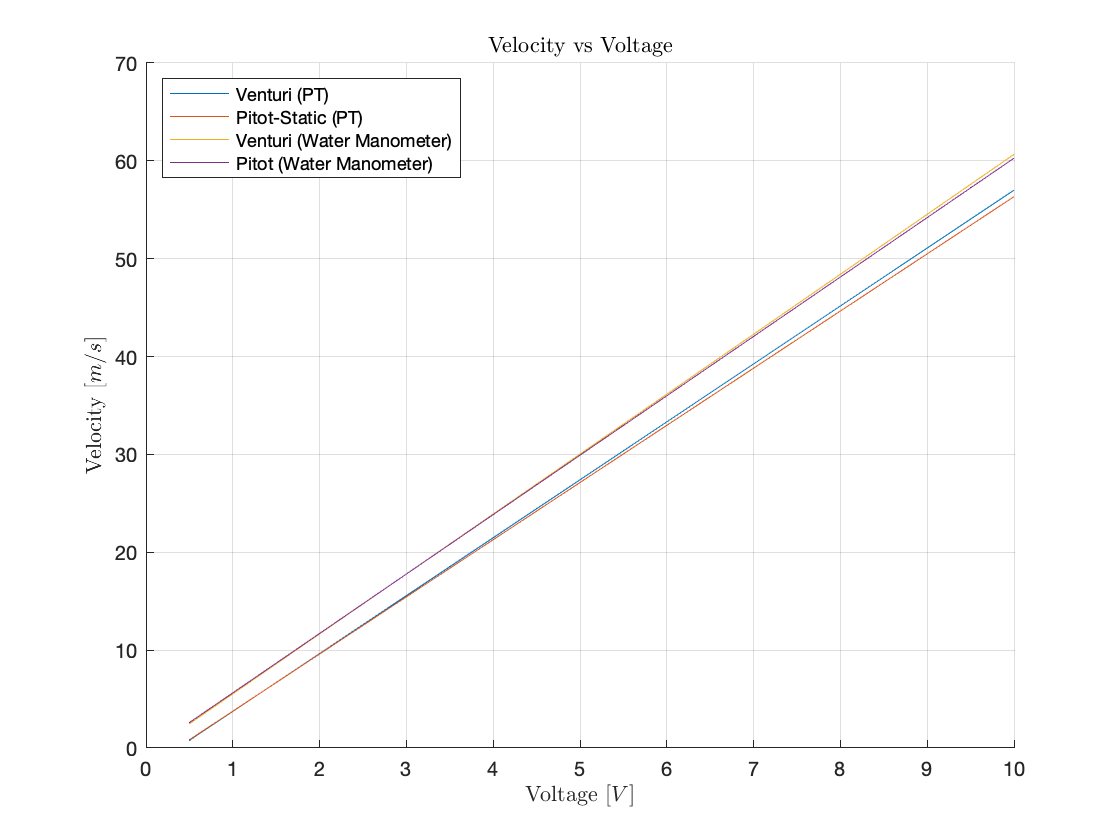


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Creating the final plot
    VenturiV = polyfit(VelocityDataVenturi(:, 3),VelocityDataVenturi(:, 1),1);
    PitotV = polyfit(VelocityDataPitot(:, 3),VelocityDataPitot(:, 1),1);
    PitotVMano = polyfit(v_pitot(:,1),v_pitot(:,2),1 );
    VenturiVMano = polyfit(v_venturi(:,1),v_venturi(:,2),1 );
    
    VenturiVManoLine = VenturiVMano(1)*v_venturi(:,1) + VenturiVMano(2);
    PitotVManoLine = PitotVMano(1)*v_venturi(:,1) + PitotVMano(2);
    PitotVLine = PitotV(1)*v_venturi(:,1) + PitotV(2);
    VenturiVLine = VenturiV(1)*v_venturi(:,1) + VenturiV(2);
    
    %% Velocity voltage plot
    figure
        hold on
    plot(VelocityDataVenturi(:, 3),VenturiVLine(:, 1))
    plot(VelocityDataVenturi(:, 3),PitotVLine(:, 1))
    plot(VelocityDataVenturi(:,3),VenturiVManoLine(:,1))
    plot(VelocityDataVenturi(:,3),PitotVManoLine(:,1))

    xlabel('Voltage [$V$]', 'FontSize',)
    ylabel('Velocity [$m/s$]')
    legend({'Venturi (PT)', 'Pitot-Static (PT)', 'Venturi (Water Manometer)', 'Pitot (Water Manometer)'}, 'Location', 'northwest')
    title('Velocity vs Voltage')
    grid on
    hold off

    
    set(0,'defaultTextInterpreter','latex')

THIS IS BOUNDARY LAYER CODE TAKEN FROM PROFESSOR HODGKINSON

% for i = 1:11
%     blfiles{i} = dir(['Aero Lab Windtunnel Calibration/Aero Lab 1 - 2019 Group Data/BoundaryLayerData/Port ',num2str(i),'/*.csv']);
%     %access this by blfiles{1}(1).name for port 1 first file
% end
% 
% for j =1:11
%     x=blfiles{j};
%     num_elements(j) = sum(arrayfun(@(x) ~isempty(x.name),x)); %number of datafiles for each port
% end
% 
% clear i j
% 
% for i = 1:11 %port incrementer
%     for j = 1:num_elements(i) %number of files in a port incrementer
% 
%         data = load([blfiles{i}(j).folder,'/',blfiles{i}(j).name]);
%         %need to group based on data(:,6)
%         y = data(:,6);
%         y_ind = find(diff(y)>.2); %indicies that correspond to the change of position
% 
%         y_ind = [0;y_ind;length(y)];
%         %and now group the data
%         R = 287;
%         bobby = NaN(length(y_ind)-1,8); %preallocate for speeeed!
%         for b = 1:length(y_ind)-1
%            temp = mean(data(y_ind(b)+1:y_ind(b+1),:)); %the grouped data based on vertical position and then averaged across all samples
%            bobby(b,:) = [temp,sqrt(2*temp(4)*(R*temp(2)/temp(1)))]; %put in the probe airspeed as part of the array
%            %bobby is an array of the collapsed data (one row per vertical location
%            %and the probe airspeed in the 8th column. Note: for one data
%            %file only
%         end
% 
%         offset = .5; %wall thickness of the pitot probe
%         freestream = bobby(end,8); % freestream velocity
%         ylocation = [0;bobby(1:end-1,6) + offset]; %vertical location
%         probespeeds = [0;bobby(1:end-1,8)]; %airspeed sensed by probe
% 
%         %group things based on the port number
%         
%         port(i).test(j).freestream = freestream;
%         port(i).test(j).ylocation = ylocation;
%         port(i).test(j).probespeeds = probespeeds;
%         port(i).test(j).density = temp(1)/(R*temp(2));
%     end
%     
%     %% Now to find the thickness at the port
%     
%     temptable = struct2table(port(i).test);
%     port(i).meanfreestream = mean(temptable.freestream);
%     port(i).meandensity = mean(temptable.density);
%     port(i).yloca = [port(i).test(1).ylocation;port(i).test(2).ylocation];
%     port(i).speeds = [port(i).test(1).probespeeds;port(i).test(2).probespeeds];
%     
%     %figure(i);plot(port(i).speeds,port(i).yloca,'.')
%     f = fit(probespeeds,ylocation,'exp1'); %fit some exponential to the data
%     port(i).blthickness = f(.99*port(i).meanfreestream);
%     %  figure;plot(f,probespeeds,ylocation)
%     %  hold on; plot(.95*port(i).meanfreestream,port(i).blthickness,'*')
% end
% 
% allcombine = struct2table(port);
% 
% port_real_locations = 0.0254*[9.05;10.03;11.01;11.99;12.97;13.95;14.93;15.91;16.89;17.87;18.85]; %mm
% 
% %% And now compare to theory
% mu = 1.7894e-5; %kg/(m)(s)
% densityinf = mean(allcombine.meandensity);
% Vinf = mean(allcombine.meanfreestream);
% 
% x_for_bl = linspace(min(port_real_locations),max(port_real_locations),100);
% Rex = densityinf*Vinf*x_for_bl/mu;
% 
% thick_laminar = 5.2*x_for_bl./sqrt(Rex);
% thick_turb = (0.37*x_for_bl)./(Rex.^(0.2));
% figure;plot(port_real_locations,allcombine.blthickness,'.')
% hold on;
% plot(x_for_bl,1000*thick_laminar,'-')
% plot(x_for_bl,1000*thick_turb,'--')
% xlabel('Port location [m]')
% ylabel('Boundary Layer thickness [mm]')
% legend('Data','Laminar Theory','Turbulent Theory')


CLEARING UP THE WORKSPACE

clear allcombine b blfiles bobby CompressedPitotTrialHolder CompressedVenturiTrialHolder const data Data densityinf f fivebythirteen freestream i j mu num_elements 
clear offset Pitot pitotfiles PitotTrialHolder port port_real_locations probespeeds R Rex temp temporary temporaryRow temptable thick_laminar thick_turb Venturi
clear venturifiles VenturiTrialHolder Vinf x x_for_bl y y_ind ylocation VenturiP VenturiT VenturiVLine VenturiVMano VenturiVManoLine PitotP PitotV PitotVLine PitotVMano PitotVManoLine


Air Foil Pressure And Drag Calculations

Pseudo-Code

- Input files

- parse data again based on angle of attack and airspeed

- calculate pressure at trailing edge of airfoil

- plot normalized pressure coef vs normalized chord-wise position

- do the plot for both top and bottom of the airfoil (do twice one for low angle of attack and one for high angle of attack)

- plot lift and pressure drag vs angles of attack (set airspeed)

- plot lift and pressure drag vs airspeeds (set angle of attack)

Substeps for part 3 MAKE SURE THIS IS A FUNCTION

- Extrapolate the pressure at the trailing edge from the upper and lower surfaces data

- Look at yellow sticky note for ports and which columns to get data from

- Create a line from the bottom port pressures and then extrapolate to the trailing edge

- Create a line from the top port pressures and then extrapolate to the trailing edge

- Average the two extrapolations

Between 3-4 MAKE FUNCTION FOR step 1

- Calculate the coefficient of pressure at each Scanivalve port using the measured data and the method outlined in Appendix C.

- flip the data so that it looks like what is in the lab document

Between 5-6 MAKE FUNCTION for numerical integration, lift and pressure drag calculations

- calculating normal and axial coefficients from numerical integration of coefficient of pressure 

- calculate lift and pressure drag coefficients

- plot these against angles of attack and airspeed

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% directory load for pitot tube
airfoilfiles = dir(['2002Data/AirFoilData/']);

%29 columns inside of the files
%3 different voltages at the 4 different angles of attack
%20 rows of data per air speed per angle of attack, 60 per angle of attack


for i = 3:numel(airfoilfiles)                                   %This for loop is called for every pitot data file
    AirFoil = table2array(readtable(['2002Data/AirFoilData/',airfoilfiles(i).name]));
    y = AirFoil(:,13);                                          %Applied voltage column
    y_ind = find(abs(diff(y))>0.5);
    y_ind = [0;y_ind;length(y)];
    
    Data = NaN(length(y_ind)-1, 29); 
    Data2 = NaN(length(y_ind)-1, 17);
    Data3 = NaN(length(y_ind)-1, 2);
    Data4 = NaN(length(y_ind)-1, 2);
    for j = 1:(length(y_ind)-1)                                 %This for loop will be called for parsing out the data in each file
        temp = mean(AirFoil(y_ind(j)+1:y_ind(j+1),1:29));       %Find the mean of all of those rows
        Data(j,:) = temp;                                       %Store each 
        temp2 = findRowCoefP(Data(j,:));
        Data2(j,:) = temp2;
        Data3(j,:) = [findCoefN(temp2),findCoefA(temp2)];
        Data4(j,:) = [findCoefL(Data3(j,:),temp(7)),findCoefD(Data3(j,:),temp(7))];
    end
     

   
    %Create the struct of all our data here
     AirFoilTrialHolder(i-2).v = Data;                            %Take Data from the for loop (which basically compressed the data from 1 file into a 5x7 matrix
     AirFoilTrialHolder(i-2).CP = Data2;
     AirFoilTrialHolder(i-2).CNandA = Data3;
     AirFoilTrialHolder(i-2).CLandD = Data4;
end

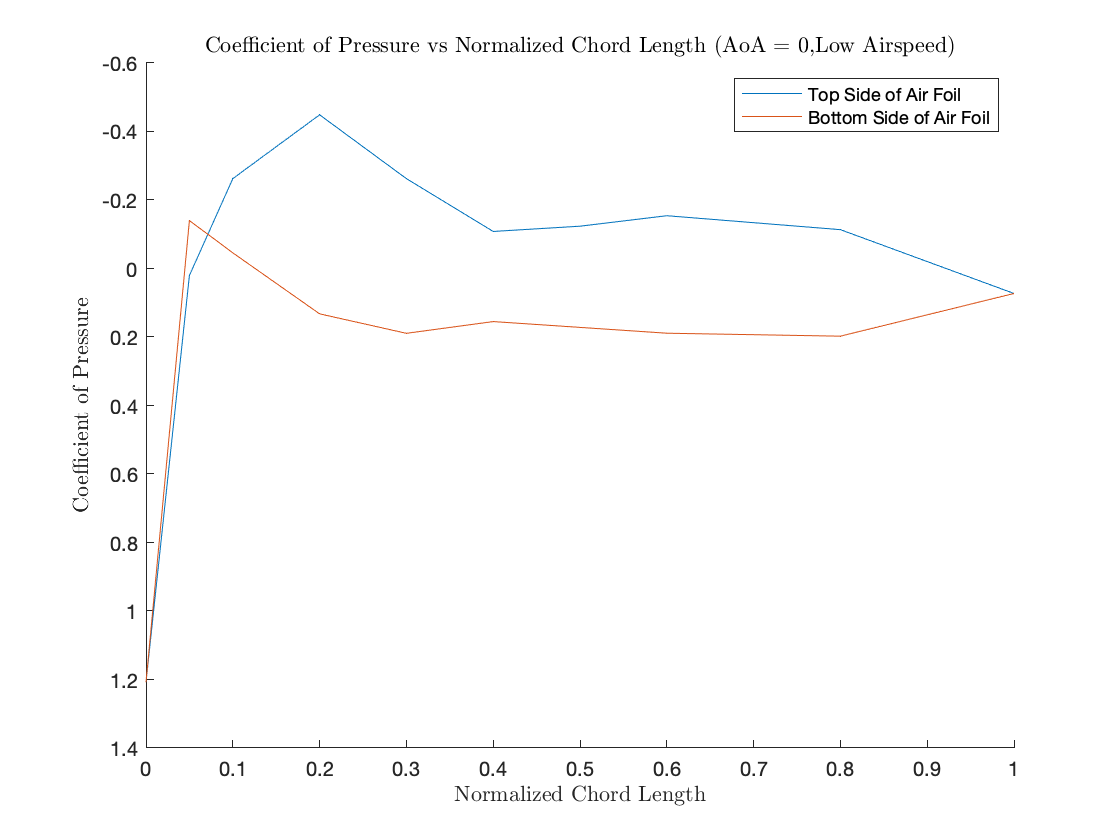

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Plotting for angle of attack zero and slow air speed
NormalizedChordLength = [0,0.175,0.35,0.7,1.05,1.4,1.75,2.1,2.8,2.8,2.1,1.4,1.05,0.7,0.35,0.175,3.5]./3.5;
BottomAirFoilCL = [NormalizedChordLength(1),NormalizedChordLength(16),NormalizedChordLength(15),NormalizedChordLength(14),NormalizedChordLength(13),NormalizedChordLength(12),NormalizedChordLength(11),NormalizedChordLength(10),NormalizedChordLength(17)];
BottomAirFoilCP = [AirFoilTrialHolder(1).CP(4,1),AirFoilTrialHolder(1).CP(4,16),AirFoilTrialHolder(1).CP(4,15),AirFoilTrialHolder(1).CP(4,14),AirFoilTrialHolder(1).CP(4,13),AirFoilTrialHolder(1).CP(4,12),AirFoilTrialHolder(1).CP(4,11),AirFoilTrialHolder(1).CP(4,10),AirFoilTrialHolder(1).CP(4,17)];
    
TopAirFoilCL = [NormalizedChordLength(1),NormalizedChordLength(2),NormalizedChordLength(3),NormalizedChordLength(4),NormalizedChordLength(5),NormalizedChordLength(6),NormalizedChordLength(7),NormalizedChordLength(8),NormalizedChordLength(9),NormalizedChordLength(17)];
TopAirFoilCP = [AirFoilTrialHolder(1).CP(4,1),AirFoilTrialHolder(1).CP(4,2),AirFoilTrialHolder(1).CP(4,3),AirFoilTrialHolder(1).CP(4,4),AirFoilTrialHolder(1).CP(4,5),AirFoilTrialHolder(1).CP(4,6),AirFoilTrialHolder(1).CP(4,7),AirFoilTrialHolder(1).CP(4,8),AirFoilTrialHolder(1).CP(4,9),AirFoilTrialHolder(1).CP(4,17)];
figure
hold on
plot(TopAirFoilCL,TopAirFoilCP);
plot(BottomAirFoilCL,BottomAirFoilCP);

xlabel('Normalized Chord Length')
ylabel('Coefficient of Pressure')
title('Coefficient of Pressure vs Normalized Chord Length (AoA = 0,Low Airspeed)')
legend('Top Side of Air Foil','Bottom Side of Air Foil')
set(gca,'ydir','reverse')
hold off

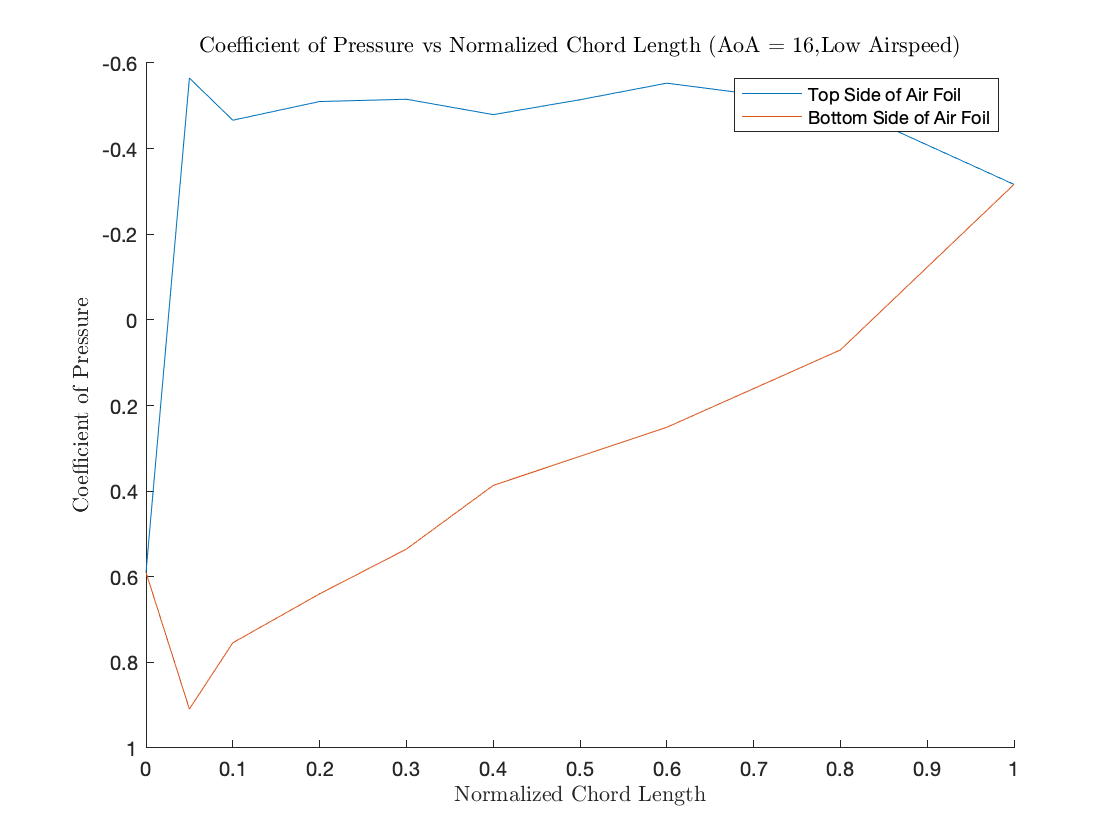



%Plotting for angle of attack 16 and slow air speed
BottomAirFoilCP = [AirFoilTrialHolder(1).CP(10,1),AirFoilTrialHolder(1).CP(10,16),AirFoilTrialHolder(1).CP(10,15),AirFoilTrialHolder(1).CP(10,14),AirFoilTrialHolder(1).CP(10,13),AirFoilTrialHolder(1).CP(10,12),AirFoilTrialHolder(1).CP(10,11),AirFoilTrialHolder(1).CP(10,10),AirFoilTrialHolder(1).CP(10,17)];
    
TopAirFoilCP = [AirFoilTrialHolder(1).CP(10,1),AirFoilTrialHolder(1).CP(10,2),AirFoilTrialHolder(1).CP(10,3),AirFoilTrialHolder(1).CP(10,4),AirFoilTrialHolder(1).CP(10,5),AirFoilTrialHolder(1).CP(10,6),AirFoilTrialHolder(1).CP(10,7),AirFoilTrialHolder(1).CP(10,8),AirFoilTrialHolder(1).CP(10,9),AirFoilTrialHolder(1).CP(10,17)];
figure
hold on
plot(TopAirFoilCL,TopAirFoilCP);
plot(BottomAirFoilCL,BottomAirFoilCP);

xlabel('Normalized Chord Length')
ylabel('Coefficient of Pressure')
title('Coefficient of Pressure vs Normalized Chord Length (AoA = 16,Low Airspeed)')
legend('Top Side of Air Foil','Bottom Side of Air Foil')
set(gca,'ydir','reverse')
hold off

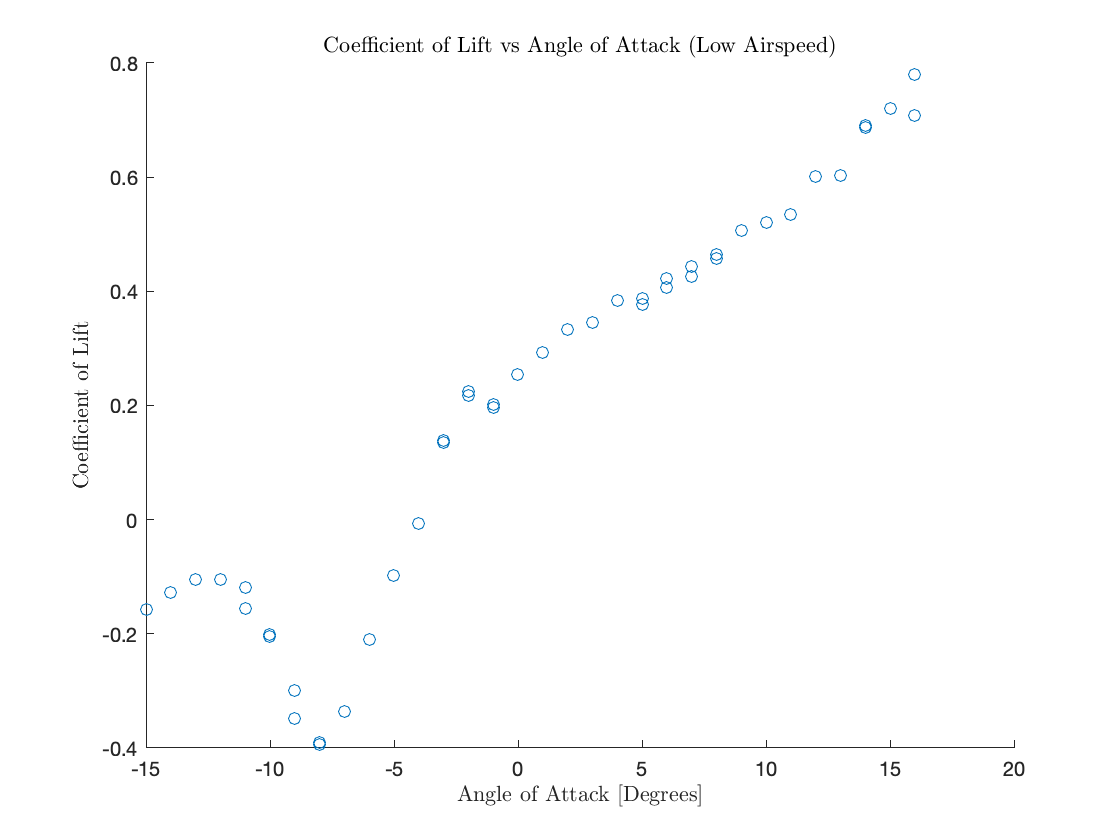

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
BigMatrixv = [AirFoilTrialHolder(1).v;AirFoilTrialHolder(2).v;AirFoilTrialHolder(3).v;AirFoilTrialHolder(4).v;AirFoilTrialHolder(5).v;AirFoilTrialHolder(6).v;AirFoilTrialHolder(7).v;AirFoilTrialHolder(8).v;AirFoilTrialHolder(9).v;AirFoilTrialHolder(10).v;AirFoilTrialHolder(11).v;AirFoilTrialHolder(12).v;AirFoilTrialHolder(13).v;AirFoilTrialHolder(14).v;AirFoilTrialHolder(15).v;AirFoilTrialHolder(16).v];
BigMatrixCLandD = [AirFoilTrialHolder(1).CLandD;AirFoilTrialHolder(2).CLandD;AirFoilTrialHolder(3).CLandD;AirFoilTrialHolder(4).CLandD;AirFoilTrialHolder(5).CLandD;AirFoilTrialHolder(6).CLandD;AirFoilTrialHolder(7).CLandD;AirFoilTrialHolder(8).CLandD;AirFoilTrialHolder(9).CLandD;AirFoilTrialHolder(10).CLandD;AirFoilTrialHolder(11).CLandD;AirFoilTrialHolder(12).CLandD;AirFoilTrialHolder(13).CLandD;AirFoilTrialHolder(14).CLandD;AirFoilTrialHolder(15).CLandD;AirFoilTrialHolder(16).CLandD];
vLowAirspeed = NaN(48,29);
CLandDLowAirspeed = NaN(48,2);
vMedAirspeed = NaN(48,29);
CLandDMedAirspeed = NaN(48,2);
for i = 1:48
    vLowAirspeed(i,:) = BigMatrixv(-2 + i*3,:);
    CLandDLowAirspeed(i,:) = BigMatrixCLandD(-2+i*3,:);
    vMedAirspeed(i,:) = BigMatrixv(-1+i*3,:);
    CLandDMedAirspeed(i,:) = BigMatrixCLandD(-1+i*3,:);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Plotting coefficient of lift vs angle of attack (low airspeed)
figure
hold on
plot(vLowAirspeed(:,7),CLandDLowAirspeed(:,1),'o');

xlabel('Angle of Attack [Degrees]')
ylabel('Coefficient of Lift')
title('Coefficient of Lift vs Angle of Attack (Low Airspeed)')
hold off

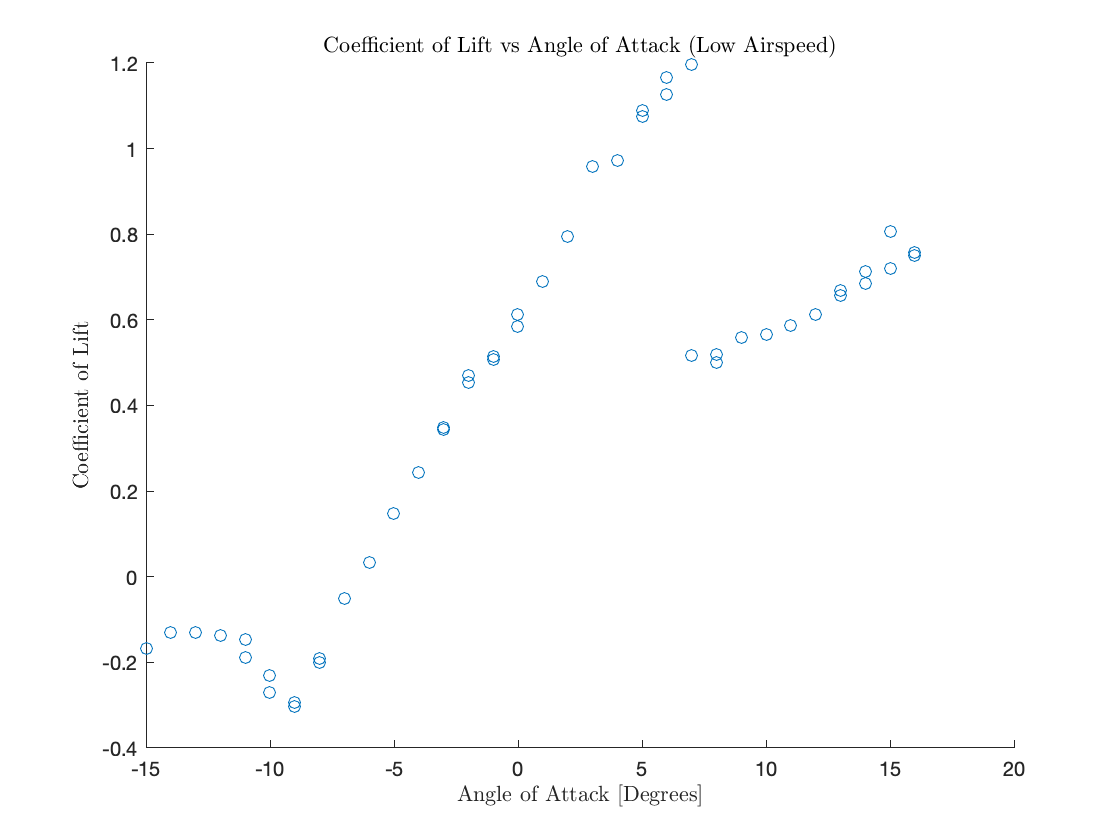


%Plotting coefficient of lift vs angle of attack (med airspeed)
figure
hold on
plot(vMedAirspeed(:,7),CLandDMedAirspeed(:,1),'o');

xlabel('Angle of Attack [Degrees]')
ylabel('Coefficient of Lift')
title('Coefficient of Lift vs Angle of Attack (Low Airspeed)')
hold off


set(0,'defaultTextInterpreter','latex')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

**Useful Functions Section**

function [wtAVG] = weightedAVG(xdataset,u_x)
    w = u_x .^(-2);
    bottomFraction = sum(w);
    topFraction = sum(w.*xdataset);
    wtAVG = topFraction/bottomFraction;
    end
%%%%%%%%%%%%%%%%%    
function [uAVG] = weightedAVGError(u_x)
    w = u_x .^(-2);
    bottomFraction = sum(w);
    uAVG = 1/sqrt(bottomFraction);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [v_pitot v_venturi] = calcVelo(venturi_T, pitot_T, venturi_P, pitot_P)
    R = 287;
    const = getConst();
    A2 = 1;
    A1 = 9.5;

    venturi_data = readmatrix('2002Data/Water_Manometer_data/venturi_water_data.csv');
    pitot_data = readmatrix('2002Data/Water_Manometer_data/pitot_water_data.csv');
    
    % sort data by voltage
    venturi_data = sort(venturi_data);
    pitot_data = sort(pitot_data);
    
    % convert to Pa
    venturi_data(:, 2) = venturi_data(:,2) * 284.84;  % in H2O to Pa
    pitot_data(:, 2) = pitot_data(:, 2) * 284.84; % in H20 to Pa
    
    vent_index = ones(20, 1);
    pitot_index = ones(20, 1);
 
    %indices corresponding to pressure differentials
    vent_index(2:end) = vent_index(2:end) .* find(diff(venturi_data(:,1)) > .2);
    pitot_index(2:end) = pitot_index(2:end) .* find(diff(pitot_data(:,1)) > .2);
    
    % preallocate
    v_venturi = zeros(length(vent_index), 2);
    v_pitot = zeros(length(pitot_index), 2);
    errorVenturi = zeros(length(vent_index),1);
    errorPitot = zeros(length(pitot_index),1);
   
    avg_venturi_data = zeros(length(vent_index), 2);
    avg_pitot_data = zeros(length(pitot_index), 2);
    
    %% Average data for venturi tube
    for i = 1:length(vent_index)
        
        if i == length(vent_index)
            avg_venturi_data(i, 1) = venturi_data(end, 1);
            avg_venturi_data(i, 2) = mean(venturi_data(vent_index(i) + 1:length(venturi_data), 2));
            
            break
        end
        
        avg_venturi_data(i, 1) = venturi_data(vent_index(i + 1));
        avg_venturi_data(i, 2) = mean(venturi_data(vent_index(i) + 1:vent_index(i + 1), 2));
        
        if i == 1
            avg_venturi_data(1, 2) = mean(venturi_data(1:vent_index(i + 1), 2));
        end
    end  
    
    
%% Average data for pitot tube
    for i = 1:length(pitot_index)
        
        if i == length(pitot_index)
            avg_pitot_data(i, 1) = pitot_data(end, 1);
            avg_pitot_data(i, 2) = mean(pitot_data(pitot_index(i) + 1:length(pitot_data), 2));
            
            break
        end
        
        avg_pitot_data(i, 1) = pitot_data(pitot_index(i + 1));
        avg_pitot_data(i, 2) = mean(pitot_data(pitot_index(i) + 1:pitot_index(i + 1), 2));
        
        if i == 1
            avg_pitot_data(1, 2) = mean(pitot_data(1:pitot_index(i + 1), 2));
        end
        
    end
    
    %% Velocity calculation
    for j = 1:length(vent_index)
        v_venturi(j, 1) = avg_venturi_data(j,1);
        v_venturi(j, 2) = sqrt((2 * avg_venturi_data(j, 2) * R * venturi_T(j, 2) / (venturi_P(j,2) * (1 - (A2 / A1) ^ 2)))); % need A2 / A1, T, P
        
        v_pitot(j, 1) = avg_pitot_data(j,1);
        v_pitot(j, 2) = sqrt(2 * avg_pitot_data(j, 2) * ((R * pitot_T(j, 2)) / pitot_P(j, 2))); % need T, P
        
        errorVenturi(j) = VenturiErrorProp(avg_venturi_data(j,2), venturi_P(j,2), venturi_T(j, 2), const.waterManoError, const.ambPError, const.tempProbeError);
        errorPitot(j) = PitotErrorProp(avg_pitot_data(j,2), pitot_P(j, 2), pitot_T(j, 2), const.waterManoError, const.ambPError, const.tempProbeError);
    end
   
%% Plotting/misc things

    %figure
%     plot(venturi_data(:,1), venturi_data(:,2))
%     hold on
%     plot(pitot_data(:,1), pitot_data(:,2))
%     xlabel('Voltage [$V$]')
%     ylabel('Pressure Differential [$Pa$]')
%     title('Pressure Differential VS Voltage (From Water Manometer)')
%     grid on
%     %hold off
%     legend({'Venturi Data', 'Pitot Data'}, 'Location', 'northwest')
    
    

    %% Velocity voltage plot
    %figure
    %plot(v_pitot(:, 1), v_pitot(:, 2))
    hold on
    errorbar(v_pitot(:, 1), v_pitot(:, 2), errorPitot, 'Color', 'k')
    %plot(v_venturi(:, 1), v_venturi(:,2))
    errorbar(v_venturi(:, 1), v_venturi(:, 2), errorVenturi, 'Color', 'm')
    xlabel('Voltage [$V$]')
    ylabel('Velocity [$m/s$]')
    legend({'V_{pitot} (PT)', 'V_{venturi} (PT)', 'V_{pitot} (WM)', 'V_{venturi} (WM)'}, 'Location', 'northwest')
    title('Velocity vs Voltage For Different Techniques')
    grid on
    hold off
    
    %% Velocity voltage plot
    figure
    plot(v_pitot(:, 1), v_pitot(:, 2))
    hold on
    plot(v_venturi(:, 1), v_venturi(:,2))
    xlabel('Voltage [$V$]')
    ylabel('Velocity [$m/s$]')
    legend({'V_{pitot} (PT)', 'V_{venturi} (PT)', 'V_{pitot} (WM)', 'V_{venturi} (WM)'}, 'Location', 'northwest')
    title('Velocity vs Voltage')
    grid on
    hold off
    
    set(0,'defaultTextInterpreter','latex')
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [V] = PitotEquation(diffP, Patm, Tatm)
    const = getConst();
    syms diffP_s Patm_s Tatm_s
    velocityEquation_s = sqrt(2*diffP_s*(const.R*Tatm_s/Patm_s));
    func = @(diffP, Patm, Tatm) double(subs(velocityEquation_s,[diffP_s, Patm_s, Tatm_s],[diffP, Patm, Tatm]));
    V = func(diffP, Patm, Tatm);
    end
%%%%%%%%%%%%%%%%%
function [error] = PitotErrorProp(diffP, Patm, Tatm, diffP_e, Patm_e, Tatm_e)
    const = getConst();
    syms diffP_s Patm_s Tatm_s diffP_e_s Patm_e_s Tatm_e_s
    velocityEquation_s = sqrt(2*diffP_s*(const.R*Tatm_s/Patm_s));
    partialdiffP_s = diff(velocityEquation_s, diffP_s);
    partialPatm_s = diff(velocityEquation_s,Patm_s);
    partialTatm_s = diff(velocityEquation_s, Tatm_s);
    ErrorEquation_s = sqrt((partialdiffP_s * diffP_e_s)^2 + (partialPatm_s * Patm_e_s)^2 + (partialTatm_s * Tatm_e_s)^2);
    func = @(diffP, Patm, Tatm, diffP_e, Patm_e, Tatm_e) double(subs(ErrorEquation_s,[diffP_s, Patm_s, Tatm_s, diffP_e_s, Patm_e_s, Tatm_e_s],[diffP, Patm, Tatm, diffP_e, Patm_e, Tatm_e]));
    error = func(diffP, Patm, Tatm, diffP_e, Patm_e, Tatm_e);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [V] = VenturiEquation(diffP, Patm, Tatm)
    const = getConst();
    syms diffP_s Patm_s Tatm_s
    velocityEquation_s = sqrt((2*diffP_s*const.R*Tatm_s)/(Patm_s*(1-(1/const.TunnelAreaRatio)^2)));
    func = @(diffP, Patm, Tatm) double(subs(velocityEquation_s,[diffP_s, Patm_s, Tatm_s],[diffP, Patm, Tatm]));
    V = func(diffP, Patm, Tatm);
    end
%%%%%%%%%%%%%%%%%
function [error] = VenturiErrorProp(diffP, Patm, Tatm, diffP_e, Patm_e, Tatm_e)
    const = getConst();
    syms diffP_s Patm_s Tatm_s diffP_e_s Patm_e_s Tatm_e_s
    velocityEquation_s = sqrt((2*diffP_s*const.R*Tatm_s)/(Patm_s*(1-(1/const.TunnelAreaRatio)^2)));
    partialdiffP_s = diff(velocityEquation_s, diffP_s);
    partialPatm_s = diff(velocityEquation_s,Patm_s);
    partialTatm_s = diff(velocityEquation_s, Tatm_s);
    ErrorEquation_s = sqrt((partialdiffP_s * diffP_e_s)^2 + (partialPatm_s * Patm_e_s)^2 + (partialTatm_s * Tatm_e_s)^2);
    func = @(diffP, Patm, Tatm, diffP_e, Patm_e, Tatm_e) double(subs(ErrorEquation_s,[diffP_s, Patm_s, Tatm_s, diffP_e_s, Patm_e_s, Tatm_e_s],[diffP, Patm, Tatm, diffP_e, Patm_e, Tatm_e]));
    error = func(diffP, Patm, Tatm, diffP_e, Patm_e, Tatm_e);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [const] = getConst()
    const.tempProbeError = 0.25;    %(degrees) Temperature Probe Error
    const.dynPError = 68.95;        %(Pa) Dynamic pressure transducer error
    const.ambPError = 3450;         %(Pa) Ambient pressure transducer error
    const.waterManoError = 10.277;  %(Pa) 
    const.R = 287.058;              %(J/kgK)
    const.TunnelAreaRatio = 9.5;    %For venturi tube
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [rowOfCoefP] = findRowCoefP(LineOfData)
    rowOfCoefP = NaN(1,17);
    for i = 1:16
        CoefP = findCoefP(LineOfData(1,i+13),LineOfData(1,2),LineOfData(1,3),LineOfData(1,4));
        rowOfCoefP(1,i) = CoefP;
    end
    trailingEdgeP = findTrailingEdge(LineOfData);
    CoefP = findCoefP(trailingEdgeP,LineOfData(1,2),LineOfData(1,3),LineOfData(1,4));
    rowOfCoefP(1,17) = CoefP;
end
%%%%%%%%%%%%%%%%%
function [trailingEdgeP] = findTrailingEdge(LineOfData)
    estimateXcoord = 3.5;
    
    %Top half of the airfoil extrapolation
    x = [1.05,1.4,1.75,2.1,2.8];
    SVP = [LineOfData(1,18),LineOfData(1,19),LineOfData(1,20),LineOfData(1,21),LineOfData(1,22)]; %SVP is the scanivalve pressure stuff
    Ptop = polyfit(x,SVP,1);
    TopEstimate = Ptop(1)*estimateXcoord + Ptop(2);
    
    %Bottom half of the airfoil extrapolation
    x= [1.05,1.4,2.1,2.8];
    SVP = [LineOfData(1,26),LineOfData(1,25),LineOfData(1,24),LineOfData(1,23)];
    Pbot = polyfit(x,SVP,1);
    BotEstimate = Pbot(1)*estimateXcoord + Pbot(2);
    
    trailingEdgeP = (TopEstimate+BotEstimate)/2;
end
%%%%%%%%%%%%%%%%%
function [calculateCoefP] = findCoefP(Pstatic,Pinfinity,rho,v)
    calculateCoefP = (Pstatic) / (0.5 * rho * v^2);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [calculateCoefN] = findCoefN(LineOfData)
NormalizedChordLengthX = [0,0.175,0.35,0.7,1.05,1.4,1.75,2.1,2.8,3.5,2.8,2.1,1.4,1.05,0.7,0.35,0.175]./3.5;
UseableLineOfCP = [LineOfData(1),LineOfData(2),LineOfData(3),LineOfData(4),LineOfData(5),LineOfData(6),LineOfData(7),LineOfData(8),LineOfData(9),LineOfData(17),LineOfData(10),LineOfData(11),LineOfData(12),LineOfData(13),LineOfData(14),LineOfData(15),LineOfData(16)];
calculateCoefN = -sum((NormalizedChordLengthX(1,2:17) - NormalizedChordLengthX(1,1:16)) .* (UseableLineOfCP(1,1:16)+UseableLineOfCP(1,2:17)) .* 0.5);
end
%%%%%%%%%%%%%%%%%
function [calculateCoefA] = findCoefA(LineOfData)
NormalizedChordLengthY = [0.14665,0.33075,0.4018,0.476,0.49,0.4774,0.4403,0.38325,0.21875,0,0,0,0,0,0.0014,0.0175,0.03885]./3.5;
UseableLineOfCP = [LineOfData(1),LineOfData(2),LineOfData(3),LineOfData(4),LineOfData(5),LineOfData(6),LineOfData(7),LineOfData(8),LineOfData(9),LineOfData(17),LineOfData(10),LineOfData(11),LineOfData(12),LineOfData(13),LineOfData(14),LineOfData(15),LineOfData(16)];
calculateCoefA = sum((NormalizedChordLengthY(1,2:17) - NormalizedChordLengthY(1,1:16)) .* (UseableLineOfCP(1,1:16)+UseableLineOfCP(1,2:17)) .* 0.5);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [calculateCoefL] = findCoefL(LineOfData,AngleofAttack)
calculateCoefL = LineOfData(1)*cosd(AngleofAttack) - LineOfData(2)*sind(AngleofAttack);
end
%%%%%%%%%%%%%%%%%
function [calculateCoefD] = findCoefD(LineOfData,AngleofAttack)
calculateCoefD = LineOfData(1)*sind(AngleofAttack) + LineOfData(2)*cosd(AngleofAttack);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

TO DO LIST:

- Debug error code **ASK TA **

- Compare velocity data with other people (Matt water manometer as well as Ben)

- Extrapolate the test data for each airfoil file to get trailing edge pressure

- Ask TA about Cp equation

- Units on graphs

figure out coefficient of P equation